## **Importing, Visualizing and Annotating Videos**

### Import Video

winopen('ball.avi')

### Import videos using system objects

videoFReader = vision.VideoFileReader('ball.avi') 

videoFReader =   vision.VideoFileReader with properties:

               Filename: 'C:\Users\aysenur.akdeniz\Desktop\Computer Vision w Matlab\Importing, Visualizing and Annotating Videos\ball.avi'
              PlayCount: 1
        ImageColorSpace: 'RGB'
    VideoOutputDataType: 'single'



% get a list of properties
properties(videoFReader)

Properties for class vision.VideoFileReader:

    Filename
    PlayCount
    ImageColorSpace
    VideoOutputDataType
    AudioOutputDataType
    AudioOutputPort




% set the data type format 
videoFReader.VideoOutputDataType = 'double';

% or you can specify it while object creation
%videoFReader = vision.VideoFileReader('ball.avi', 'VideoOutputDataType', 'double') 

### Processing Video Frames

methods(videoFReader)

Methods for class vision.VideoFileReader:

VideoFileReader  info             isLocked         reset            
clone            isDone           release          step             

Methods of vision.VideoFileReader inherited from handle.



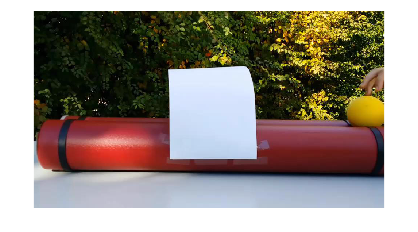

%{
while videoFReader.isDone==0
    videoFrame = videoFReader();
    imshow(videoFrame)
end
%}

videoFrame = videoFReader();
imshow(videoFrame)

### Playing Videos

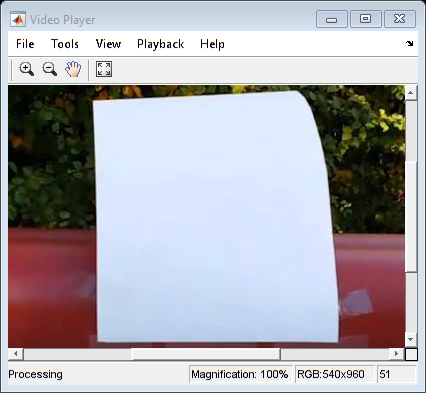

videoPlayer = vision.VideoPlayer;

while ~videoFReader.isDone
    videoFrame = videoFReader();
    videoPlayer(videoFrame);
end

reset(videoFReader);
release(videoFReader);
